### This links with `plot_regression_template.mlx` (for comparison between regression and interpolation)

Data 

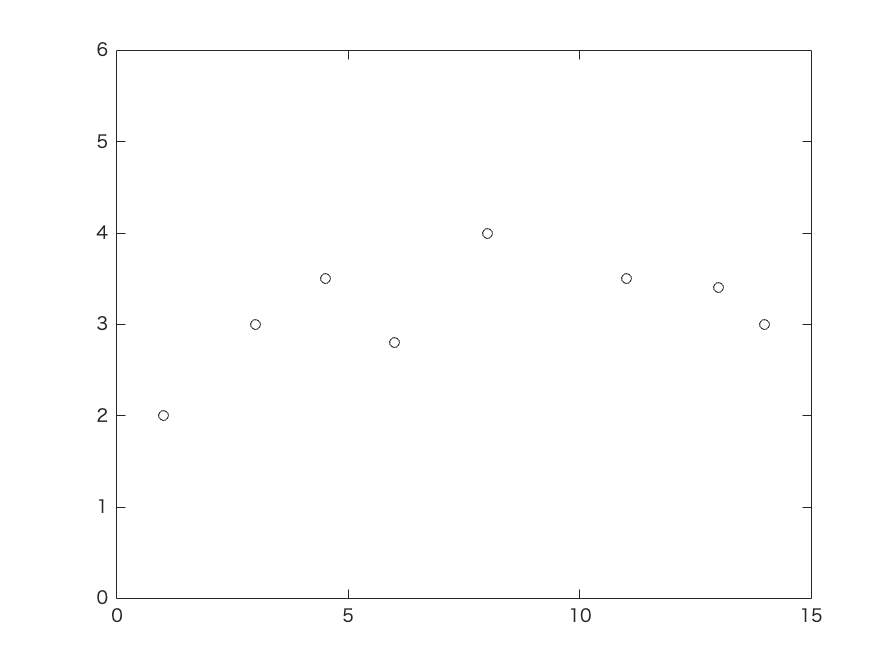

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];

figure
plot(x,y , 'ko')
hold on
axis([0, 15, 0, 6])
hold off

Linear interpolation (points 1 & 8)

xx = [x(1), x(8)]

xx =      1    14


yy = [y(1), y(8)]

yy =      2     3



p1 = polyfit(xx, yy, 1)

p1 =     0.0769    1.9231


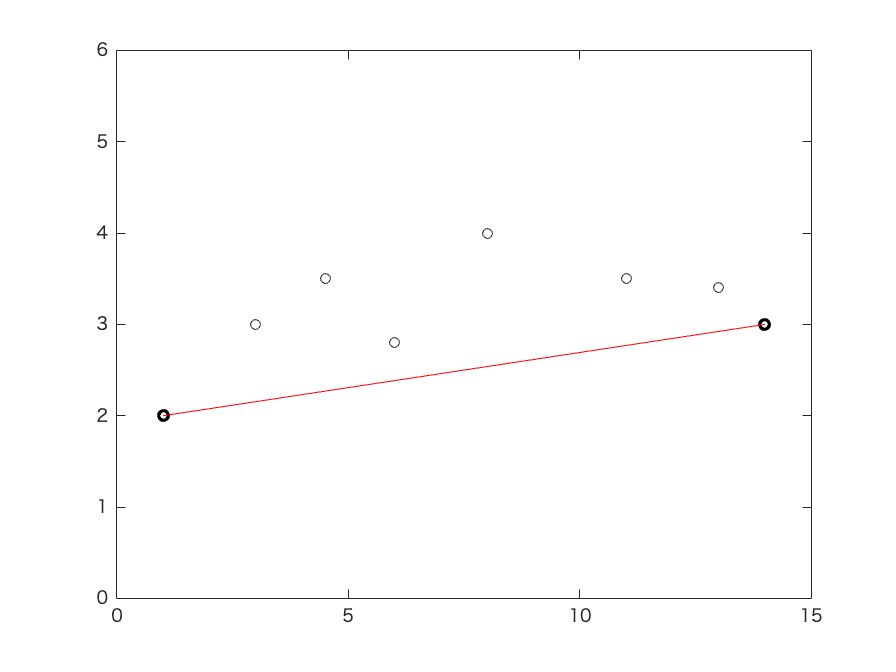


xxx = 1:0.1:14;
yyy1 = polyval(p1, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy1, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

Quadratic polynomial interpolation (points 1,5,8)

xx = [x(1), x(5), x(8)]

xx =      1     8    14


yy = [y(1), y(5), y(8)]

yy =      2     4     3



p2 = polyfit(xx, yy, 2)

p2 =    -0.0348    0.5989    1.4359


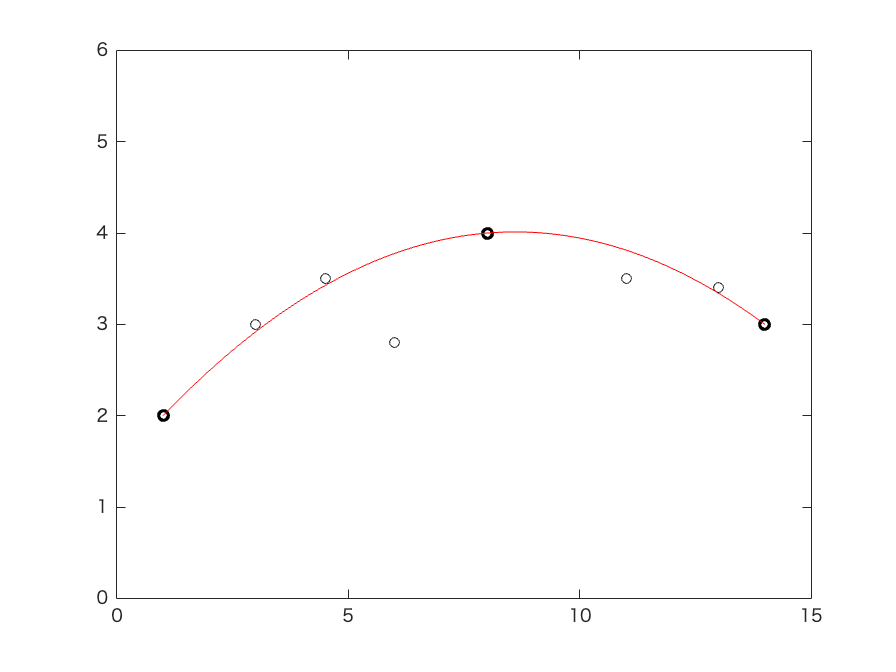


xxx = 1:0.1:14;
yyy2 = polyval(p2, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy2, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

Cubic polynomial interpolation (points 1,3,6,8)

xx = [x(1), x(3), x(6), x(8)]

xx =     1.0000    4.5000   11.0000   14.0000


yy = [y(1), y(3), y(6), y(8)]

yy =     2.0000    3.5000    3.5000    3.0000



p3 = polyfit(xx, yy, 3)

p3 =     0.0019   -0.0750    0.7909    1.2822


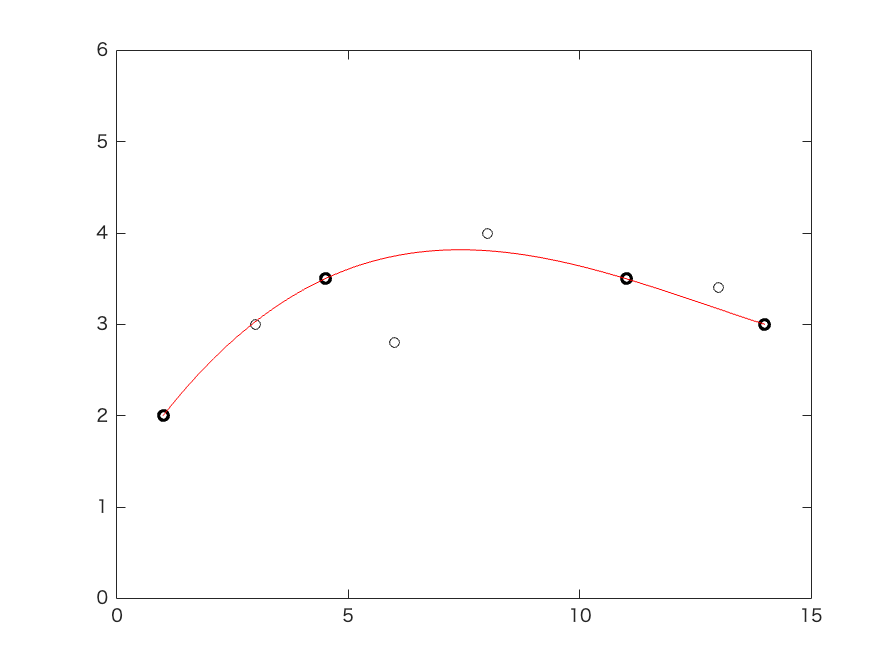


xxx = 1:0.1:14;
yyy3 = polyval(p3, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy3, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

7th-order polynomial interpolation

% using normal polynomial interpolation fitting
p7 = polyfit(x, y, 7)

p7 =    -0.0001    0.0048   -0.1036    1.1597   -7.0728   22.8676  -34.5103   19.6548


yy7 = polyval(p7, xxx)

yy7 =     2.0000    1.4886    1.1107    0.8485    0.6857    0.6075    0.6002    0.6518    0.7512    0.8884    1.0548    1.2423    1.4441    1.6542    1.8673    2.0788    2.2850    2.4825    2.6689    2.8419    3.0000    3.1420    3.2672    3.3750    3.4654    3.5387    3.5951    3.6353    3.6602    3.6708    3.6680    3.6533    3.6277    3.5927    3.5497    3.5000    3.4451    3.3862    3.3249    3.2624    3.1999    3.1387    3.0798    3.0244    2.9733    2.9275    2.8876    2.8545    2.8285    2.8102



% test using spline to compare
p7s = spline(x, y)

p7s = フィールドをもつ struct :
      form: 'pp'
    breaks: [1 3 4.5000 6 8 11 13 14]
     coefs: [7×4 double]
    pieces: 7
     order: 4
       dim: 1


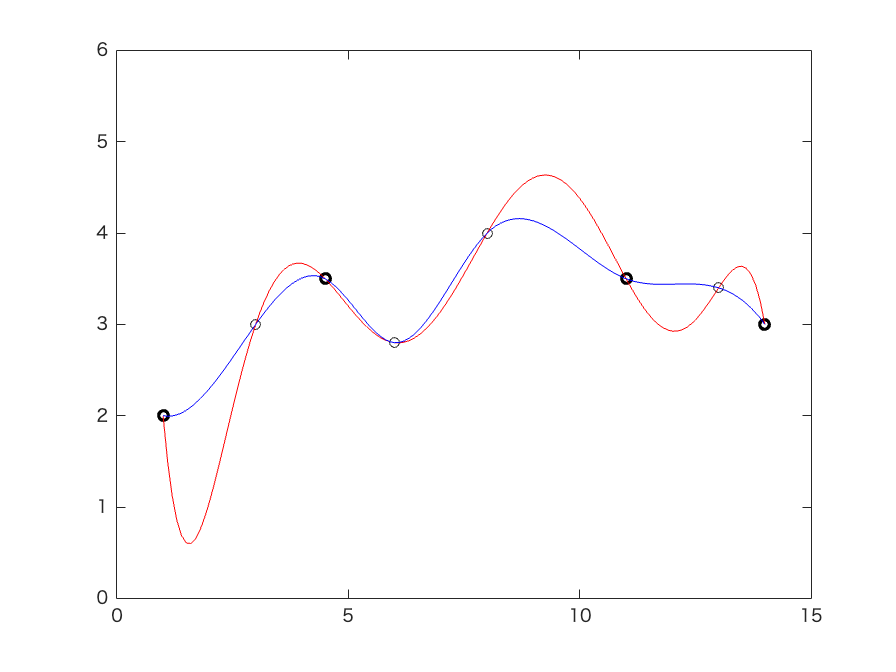


figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(1:0.1:14, yyy7, 'r-')
hold on
axis([0, 15, 0, 6])
% start testing this with spline
hold on
plot(1:0.1:14, ppval(p7s, 1:0.1:14), 'b-')
hold off


% for the polynomial interpolation part,
% compare this with the last graph in plot_regression_template.mlx
% both are the same graph